# ECSE403: Lab7

Jiahua Liang (260711529)

Frederic Cyr (260674545)

Xijun Liu (260654285)


% Question 1

%constants given in lab3
Kg=3.7;
rg=0.0064;
mc=0.526;
kth=0.00153;
mp=0.106*2;
%constants given in lab1
Jm=0.01;
Ke=0.02;
Kt=0.02;
%new constants
Km = 0.0077;
Rm = 2.6;
g =9.81;
alpha = (Kg*Km)/(rg*Rm);
beta= (alpha^2)*Rm;
lp = 0.336*2;

A = [0,1,0,0;
    0,(-beta)/(mc),(-mp*g)/mc,0;
    0,0,0,1;
    0,(beta)/(mc*lp),g/(lp),0];
B = [0;alpha/(mc);0;-alpha/(mc*lp)];
C = eye(4);
D=[0;0;0;0];

Q= [120,0,0,0;
    0,1,0,0;
    0,0,120,0;
    0,0,0,0]

Q =    120     0     0     0
     0     1     0     0
     0     0   120     0
     0     0     0     0


R=0.01

R = 0.0100

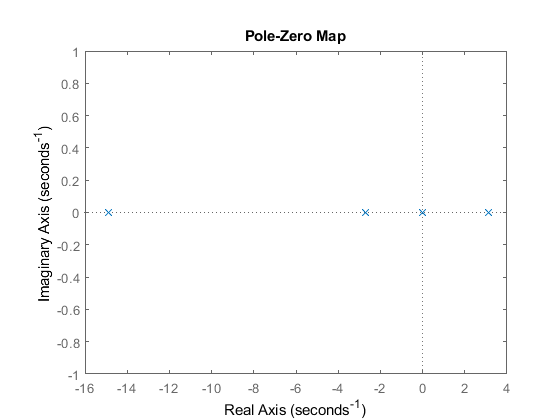


G = ss(A,B,C,D);
tf(G);

[p,z]=pzmap(G);
pzmap(G);


eigenvalue_A=eig(A);

Co=ctrb(A,B);
rank_Co=rank(Co);

Mp=0.15;
ts=2.5;
zeta=((log(Mp)^2)/(pi^2+log(Mp)^2))^0.5;
wn=3.9/(zeta*ts);
Pd1=-zeta*wn+(wn*(1-zeta^2)^0.5)*1i;
Pd2=-zeta*wn-(wn*(1-zeta^2)^0.5)*1i;

Pnd1= 15*Pd1;
Pnd2= 15*Pd2;

p = [Pd1 Pd2 Pnd1 Pnd2];
%K1 = place(A,B,p)

%Question 6 
K = lqr(A,B,Q,R)

K =  -109.5445 -101.7170 -252.6880  -76.6781


%Question 7
%K = [-223.6068, -145.8560, -351.1372, -55.9088]

